# Affinity Matrix & Transition Matrix

- Tune bandwidth to know when the outliers occur.

- What happen to transition matrix if the bandwidth is too small. What is eigenvalue and eigenvector of identity matrix.

- What happen to transition matrix if the bandwidth is too large. What is eigenvalue and eigenvector of all ones matrix.

## Fix data points

clc; clear; close all;
use_fix_dataset = true; % use this to observe relation between bandwidth and outlier.
sigma = 0.7; % distribution region of data.
outlier_bool = true;
outlier_dist = 2;
if ~use_fix_dataset
    X = normrnd(0, sigma, 4, 2);
    if outlier_bool
        X = [X; outlier_dist, outlier_dist];
    end
else
    X = [-0.74, -1; -0.13, -0.98; 0.24, -0.58; 0.61, 0.73; 2., 2.];
end
n = size(X, 1);

## Construct distance matrix

- L1, L2, sup norm

- [Mahalanobis distance](https://arxiv.org/abs/1804.02811)

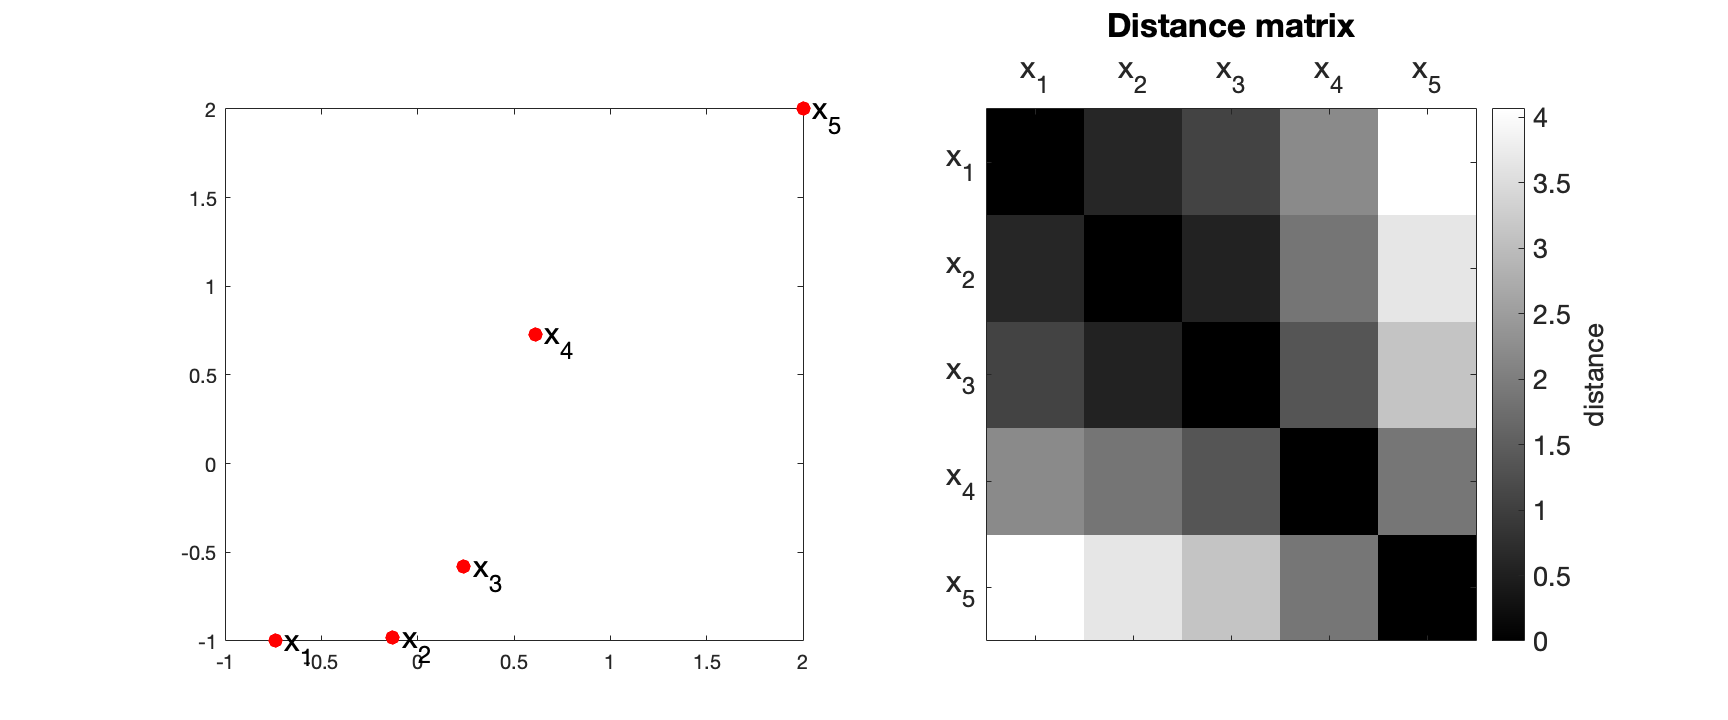

bandwidth = 1; % kernel bandwidth
dist_type = 'euclidean';

dist_matrix = squareform(pdist(X, dist_type)); % distance matrix

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1, 2, 1)
plot(X(:, 1), X(:, 2), 'r.','MarkerSize',25)
for i = 1:n
    text(X(i, 1)+sigma/15, X(i, 2)-sigma/20, ['x_', num2str(i)], 'fontsize',15)
end

subplot(1, 2, 2)
imagesc(dist_matrix, [min(dist_matrix(:)), max(dist_matrix(:))])
colormap(gray);
% ylabel('row of matrix', 'fontsize', 15)
% xlabel('column of matrix', 'fontsize', 15)
xticks([1,2,3,4,5])
yticks([1,2,3,4,5])
xticklabels({'x_1','x_2','x_3','x_4','x_5'})
yticklabels({'x_1','x_2','x_3','x_4','x_5'})
set(gca, 'fontsize',15)
set(gca,'xaxisLocation','top')
a = colorbar;
a.Label.String = 'distance';
title('Distance matrix')

## Affinity matrix

Here, the heat kernel is used $k_{\epsilon}(x,y) = exp\left(\frac{\|x-y\|^2}{\epsilon^2}\right)$.

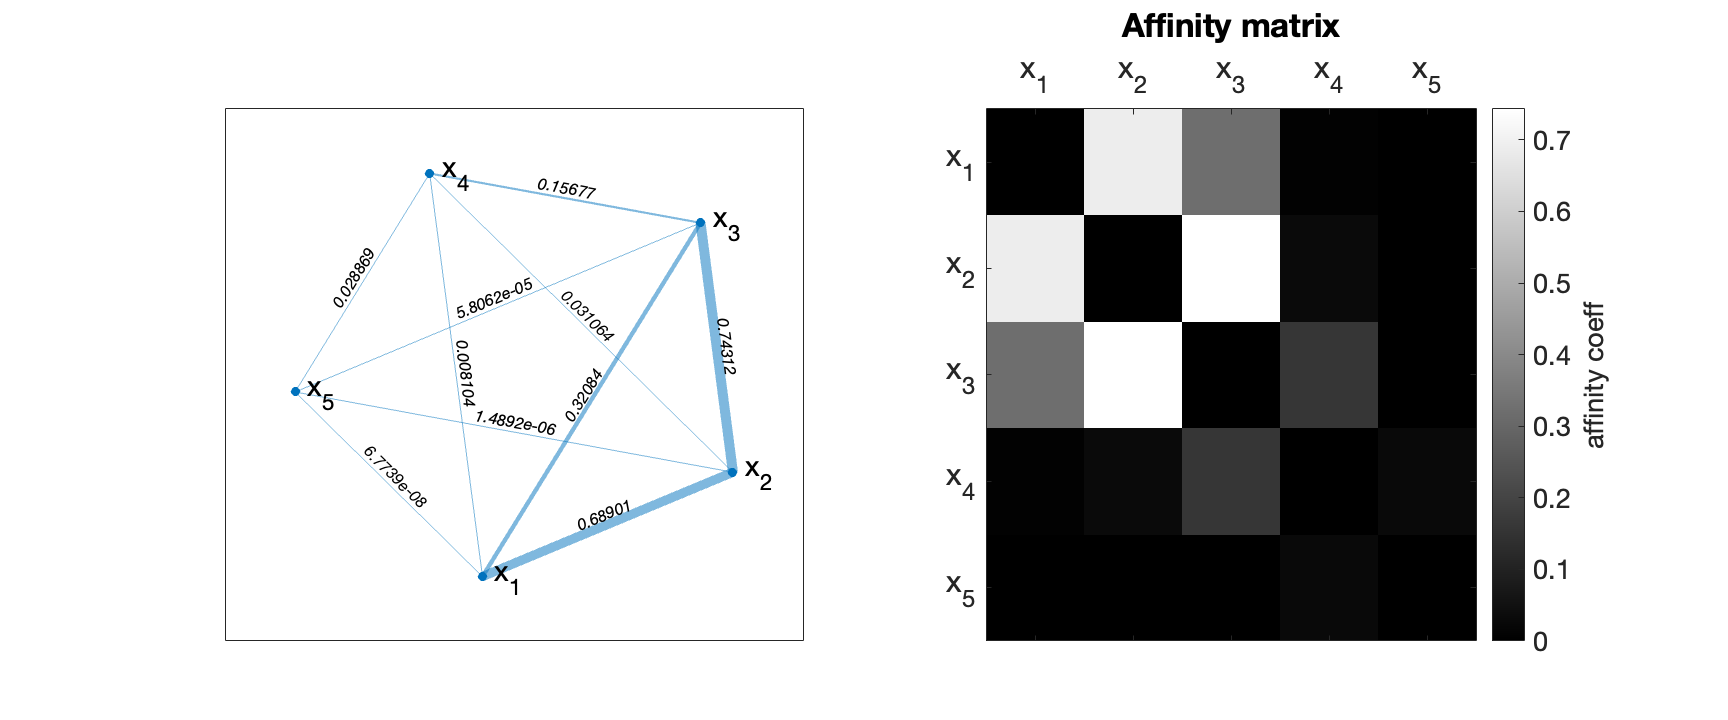

W = exp(-dist_matrix.^2/bandwidth^2); % affinity matrix
for i = 1:n
    W(i, i) = 0; % no self-loop
end

starts = []; terminals = []; weights = [];
for i = 1:n
    for j = i+1:n
        starts = [starts, i];
        terminals = [terminals, j];
        weights = [weights, W(i, j)];
    end
end
G = graph(starts, terminals, weights);
% LWidths = 5*G.Edges.Weight/max(G.Edges.Weight);
LWidths = 5*(G.Edges.Weight-min(G.Edges.Weight))/max((G.Edges.Weight-min(G.Edges.Weight)));
LWidths(LWidths == 0) = 1e-7;

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1, 2, 1)
h = plot(G,'EdgeLabel',G.Edges.Weight,'LineWidth',LWidths, 'NodeFontSize', 14);
if n == 4
    labelnode(h, [1 2 3 4],{'x_1', 'x_2', 'x_3', 'x_4'})
elseif n == 5
    labelnode(h, [1 2 3 4 5],{'x_1', 'x_2', 'x_3', 'x_4', 'x_5'})
end



subplot(1, 2, 2)
imagesc(W, [min(W(:)), max(W(:))])
colormap(gray);
% ylabel('row of matrix', 'fontsize', 15)
% xlabel('column of matrix', 'fontsize', 15)
xticks([1,2,3,4,5])
yticks([1,2,3,4,5])
xticklabels({'x_1','x_2','x_3','x_4','x_5'})
yticklabels({'x_1','x_2','x_3','x_4','x_5'})
set(gca, 'fontsize',15)
set(gca,'xaxisLocation','top')
a = colorbar;
a.Label.String = 'affinity coeff';
title('Affinity matrix')

## Transition matrix


$$K=D^{-1}W$$


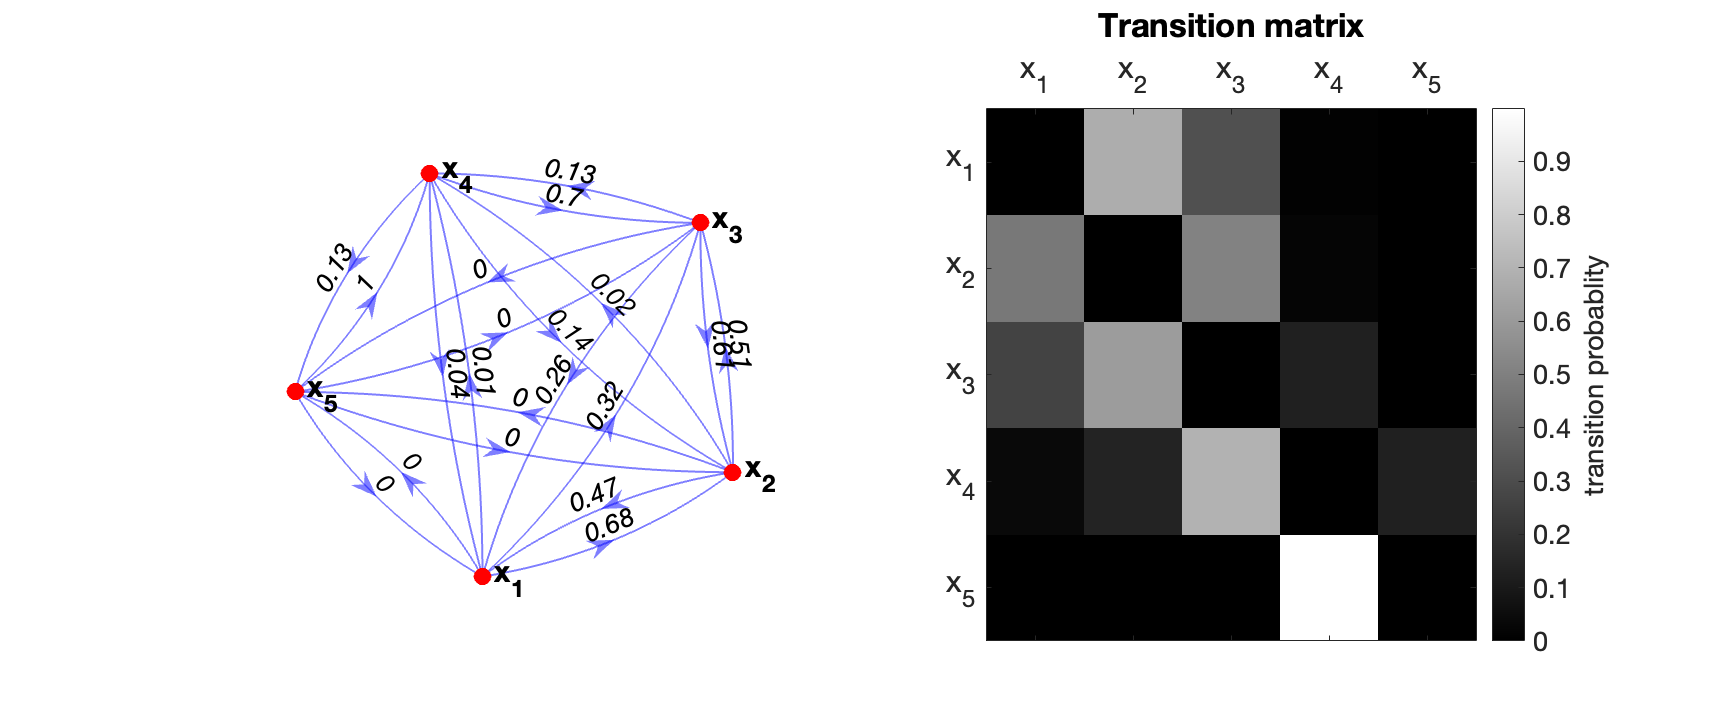

D = diag(sum(W));
K = inv(D)*W;

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1,2,1)
if n == 5
    mc = dtmc(K, 'StateNames',["x_1" "x_2" "x_3" "x_4" "x_5"]);
elseif n == 4
    mc = dtmc(K, 'StateNames',["x_1" "x_2" "x_3" "x_4"]);
end
h =graphplot(mc,'LabelEdges', true);
h.NodeFontSize = 15;
h.EdgeFontSize = 13;

subplot(1,2,2)
imagesc(K, [min(K(:)), max(K(:))])
colormap(gray);
xticks([1,2,3,4,5])
yticks([1,2,3,4,5])
xticklabels({'x_1','x_2','x_3','x_4','x_5'})
yticklabels({'x_1','x_2','x_3','x_4','x_5'})
set(gca, 'fontsize',15)
set(gca,'xaxisLocation','top')
a = colorbar;
a.Label.String = 'transition probablity';
title('Transition matrix')

## Find eigenvector

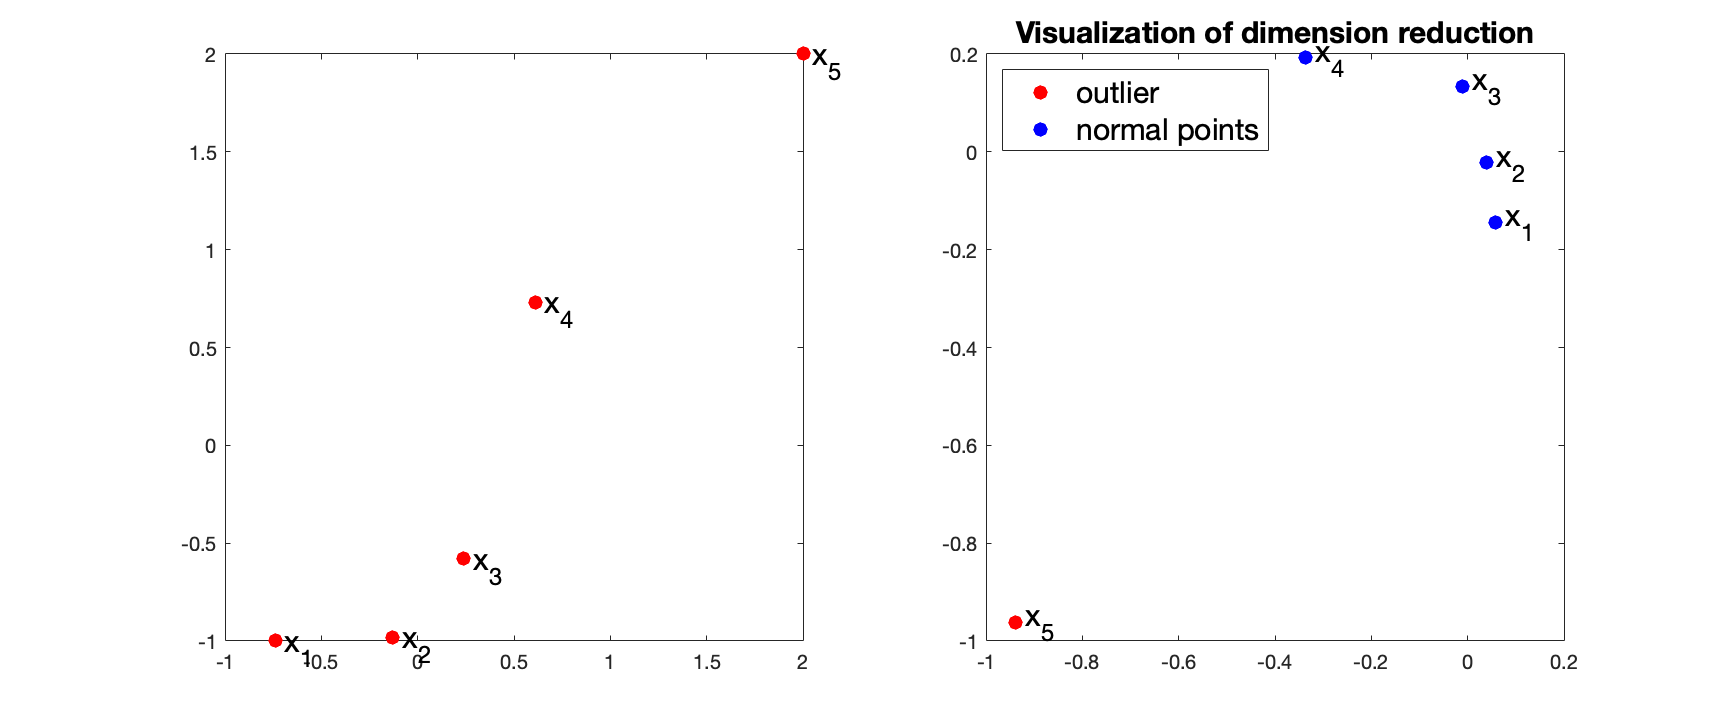

[U, L] = eig(K);
[~, idx] = sort(diag(L), 'descend');
U = U(:, idx);

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1,2,1)
plot(X(:, 1), X(:, 2), 'r.','MarkerSize',25)
for i = 1:n
    text(X(i, 1)+sigma/15, X(i, 2)-sigma/20, ['x_', num2str(i)], 'fontsize',15)
end

subplot(1, 2, 2)
if n == 5
    plot(U(end, 2), U(end, 3), 'r.','MarkerSize',25)
    hold on
    plot(U(1:end-1, 2), U(1:end-1, 3), 'b.','MarkerSize',25)
    legend('outlier', 'normal points', 'Location','northwest', 'fontsize', 15)
    title('Visualization of dimension reduction', 'fontsize', 15)
elseif n == 4
    plot(U(:, 2), U(:, 3), 'r.','MarkerSize',25)
end

for i = 1:n
    text(U(i, 2)+0.02, U(i, 3), ['x_', num2str(i)], 'fontsize',15)
end

## Comparison between different kernel bandwidth

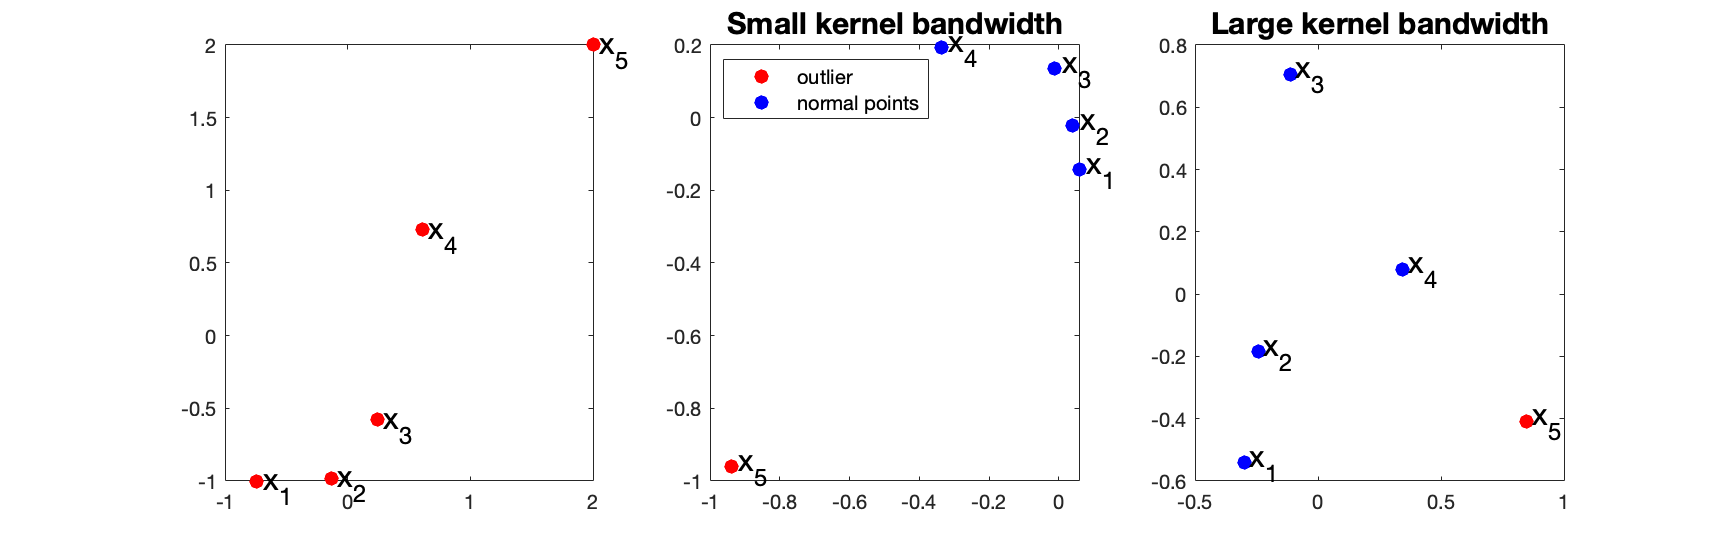

X = [-0.74, -1; -0.13, -0.98; 0.24, -0.58; 0.61, 0.73; 2., 2.];
dist_matrix = squareform(pdist(X));
bandwidth = 1.;
W = exp(-dist_matrix.^2/bandwidth^2); % affinity matrix
for i = 1:n
    W(i, i) = 0; % no self-loop
end
D = diag(sum(W));
K = inv(D)*W;
[U, L] = eig(K);
[~, idx] = sort(diag(L), 'descend');
U = U(:, idx);

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.3])
subplot(1,3,1)
plot(X(:, 1), X(:, 2), 'r.','MarkerSize',25)
for i = 1:n
    text(X(i, 1)+sigma/15, X(i, 2)-sigma/20, ['x_', num2str(i)], 'fontsize',15)
end

subplot(1, 3, 2)
if n == 5
    plot(U(end, 2), U(end, 3), 'r.','MarkerSize',25)
    hold on
    plot(U(1:end-1, 2), U(1:end-1, 3), 'b.','MarkerSize',25)
    legend('outlier', 'normal points', 'Location','northwest', 'fontsize', 10)
    title('Small kernel bandwidth', 'fontsize', 15)
elseif n == 4
    plot(U(:, 2), U(:, 3), 'r.','MarkerSize',25)
end

for i = 1:n
    text(U(i, 2)+0.02, U(i, 3), ['x_', num2str(i)], 'fontsize',15)
end

bandwidth = 2.5;
W = exp(-dist_matrix.^2/bandwidth^2); % affinity matrix
for i = 1:n
    W(i, i) = 0; % no self-loop
end
D = diag(sum(W));
K = inv(D)*W;
[U, L] = eig(K);
[~, idx] = sort(diag(L), 'descend');
U = U(:, idx);

subplot(1, 3, 3)
if n == 5
    plot(U(end, 2), U(end, 3), 'r.','MarkerSize',25)
    hold on
    plot(U(1:end-1, 2), U(1:end-1, 3), 'b.','MarkerSize',25)
%     legend('outlier', 'normal points', 'Location','northwest', 'fontsize', 10)
    title('Large kernel bandwidth', 'fontsize', 15)
elseif n == 4
    plot(U(:, 2), U(:, 3), 'r.','MarkerSize',25)
end

for i = 1:n
    text(U(i, 2)+0.02, U(i, 3), ['x_', num2str(i)], 'fontsize',15)
end